

clear; clc; close all;

## =====================================================================

cfg.variant = 'full';
% Options:
%   ''full''
%   ''simple_detector''
%   ''no_multiscale''
%   ''no_adaptive_thresholds''
%   ''no_qa_logic''
%   ''no_bio_evidence''

cfg = applyDetectorVariant(cfg);

fprintf('\n================ DETECTOR VARIANT ================\n');


================ DETECTOR VARIANT ================


disp(cfg);

                       variant: 'full'
                use_multiscale: 1
       use_adaptive_thresholds: 1
    use_cross_scale_clustering: 1
                  use_qa_logic: 1
              use_bio_evidence: 1




% ---------------------- INPUT ----------------------------------------
in_csv = 'E:\Computer vision Paper\dataset_3\manual_dataset3_detector_input.csv';
T = readtable(in_csv);

t_s    = T.time_s(:);
D_in   = T.burrow_smooth_mm(:);
v_mmps = T.dBurrow_dt_mmps(:);   % kept for backward compat; effort now uses D_ref

if ismember('mask_detected', T.Properties.VariableNames)
    detected = logical(T.mask_detected(:));
else
    detected = true(size(t_s));
end

if any(~isfinite(t_s)) || numel(t_s) < 10
    error('time_s is missing/invalid or too short.');
end

dt = median(diff(t_s), 'omitnan');
if ~isfinite(dt) || dt <= 0
    error('Bad or missing time_s sampling.');
end

t_min = t_s/60;
N = numel(t_s);
total_time_s   = t_s(end) - t_s(1);
total_time_min = total_time_s/60;

% ---------------------- USER SETTINGS --------------------------------
L = 81.33;

min_dur_min      = 5;
merge_gap_min    = 8;
start_hold_min   = 1;
end_hold_min     = 3;
min_amp_mm_floor = 1.0;

frac_dir_min_high = 0.75;
frac_dir_min_med  = 0.60;
min_anchors_high  = 20;
min_anchors_med   = 8;
warn_low_coverage_below = 0.30;

qa_primary_det_frac_min     = 0.80;
qa_secondary_det_frac_min   = 0.60;
qa_exploratory_det_frac_min = 0.50;

bio_frac_dir_min_high = 0.80;
bio_frac_dir_min_med  = 0.65;
bio_support_min_high  = 3;
bio_support_min_med   = 2;
bio_score_min_high    = 0.75;
bio_score_min_med     = 0.55;
bio_dur_scale_min     = 20;

% [v10-4] Reduced Hampel half-window: 15 s instead of 60 s.
%         At 0.5 Hz this = 7 frames — narrower than typical frozen plateaus
%         (3–20 frames) so the window median is not contaminated by them.
hampel_win_s = 15;     % [v10-4] was 60
hampel_k     = 3.5;

% [v10-1] Scale grid starts at 240 s — 120 s REMOVED.
%         Reason: at 120 s the auto signal's frozen-plateau zeros drive
%         sigma_r to the noise floor (0.05 mm/hr), start_thr is clamped
%         to 0.5, and the entire trial looks like one long bout at very
%         high mean_score, biasing reference scale selection.
if cfg.use_multiscale
    base_scales_s = [240 480 900 1800];
else
    base_scales_s = 240;
end
kStart_grid   = [2.0 2.5 3.0 3.5 4.0];

support_min_scales = 2;
overlap_min_frac   = 0.30;
support_bonus_per_extra_scale = 0.12;
support_bonus_cap             = 0.30;

max_reasonable_bouts_total = max(25, round(total_time_min/3));
hard_bout_cap              = max(60, round(total_time_min/1.5));

% ---------------------- [v10-4] HAMPEL FILTER ----------------------
D_hampel = hampelFilter(D_in, dt, hampel_win_s, hampel_k);
n_spikes_removed = sum(abs(D_hampel - D_in) > 0.01);
fprintf('[v10-4] Hampel filter: removed %d spike frames (win=%.0fs→%.0f frames, k=%.1f)\n', ...
    n_spikes_removed, hampel_win_s, hampel_win_s/dt, hampel_k);

[v10-4] Hampel filter: removed 19 spike frames (win=15s→8 frames, k=3.5)



% ---------------------- PREP -----------------------------------------
D      = fillmissingSafe(D_hampel);
D_work = D;
% NOTE: v_work_mmps is kept for API compatibility but effort is now
%       computed from D_ref gradient — see [v10-3] below.
v_work_mmps = v_mmps;

baseline_win_min = 5;
k_base = max(3, round((baseline_win_min*60)/dt));
i0 = 1:min(N, k_base);
i1 = max(1, N-k_base+1):N;

D_start = median(D(i0), 'omitnan');
D_end   = median(D(i1), 'omitnan');
net_progress_original_mm = D_end - D_start;

det_frac = mean(detected);
trial_max_gap_missing_min = maxConsecutiveGapMinutes(detected, dt);
[trial_qa_class, trial_accept_event_inference] = classifyTrialQA( ...
    det_frac, qa_primary_det_frac_min, qa_secondary_det_frac_min, qa_exploratory_det_frac_min);

fprintf('\n================= INPUT / COVERAGE =================\n');


================= INPUT / COVERAGE =================


fprintf('CSV: %s\n', in_csv);

CSV: E:\Computer vision Paper\dataset_3\manual_dataset3_detector_input.csv


fprintf('N=%d | dt=%.3f s | total=%.2f min\n', N, dt, total_time_min);

N=6001 | dt=2.000 s | total=200.00 min


fprintf('Coverage: %.1f%% | QA class: %s\n', 100*det_frac, trial_qa_class);

Coverage: 100.0% | QA class: PRIMARY



% ---------------------- ADAPTIVE CONFIDENCE -------------------------
if cfg.use_qa_logic
    min_cov_high = max(0.15, min(0.40, 0.50 * det_frac));
    min_cov_med  = max(0.05, min(0.15, 0.20 * det_frac));
    max_gap_inside_event_min_high = max(3.0, min(8.0,  3.0 + 5.0*(1-det_frac)));
    max_gap_inside_event_min_med  = max(6.0, min(12.0, 6.0 + 6.0*(1-det_frac)));
else
    min_cov_high = 0;
    min_cov_med  = 0;
    max_gap_inside_event_min_high = inf;
    max_gap_inside_event_min_med  = inf;
end

fprintf('[v10] min_cov_high=%.3f | min_cov_med=%.3f\n', min_cov_high, min_cov_med);

[v10] min_cov_high=0.400 | min_cov_med=0.150


if det_frac < warn_low_coverage_below
    warning('Low detection coverage. Adaptive rules apply.');
end

% ---------------------- SCALE LIST ----------------------------------
scales_s = base_scales_s(:)';
scales_s = scales_s(scales_s >= 7*dt);
scales_s = scales_s(scales_s <= max(600, 0.25*total_time_s));
if isempty(scales_s)
    scales_s = max(240, round(0.02*total_time_s));   % [v10-1] floor raised to 240
end

fprintf('\n================= AUTO-TUNE =================\n');


================= AUTO-TUNE =================


fprintf('[v10-1] Scale grid (120s removed): %s\n', mat2str(scales_s));

[v10-1] Scale grid (120s removed): [240 480 900 1800]



% ---------------------- PREP HOLD COUNTS ----------------------------
min_dur_s   = min_dur_min*60;
merge_gap_s = merge_gap_min*60;
k_start = max(1, round((start_hold_min*60)/dt));
k_end   = max(1, round((end_hold_min*60)/dt));
n_min   = max(3, round(min_dur_s/dt));

% ---------------------- [v10-2] PER-SCALE SIGMA WEIGHTS -------------
% Uses the new zero-aware sigma estimator — see estimateSigmaRClipped below.
scale_sigma_r = zeros(size(scales_s));
for ss = 1:numel(scales_s)
    [~, r_tmp] = buildSmoothDepthRate(D_work, dt, scales_s(ss), scales_s(ss));
    scale_sigma_r(ss) = estimateSigmaRClipped(r_tmp);
end
min_sigma = min(scale_sigma_r(isfinite(scale_sigma_r) & scale_sigma_r > 0));
scale_sigma_weight = min_sigma ./ max(scale_sigma_r, min_sigma);
fprintf('[v10-2] Per-scale sigma_r: %s\n', mat2str(round(scale_sigma_r,3)));

[v10-2] Per-scale sigma_r: [0.941 0.498 0.256 0.105]



% ---------------------- AUTO-TUNE GRID SEARCH -----------------------
gridRows = table();
bestObj  = -Inf;
bestConfig = struct();
bestConfig.kStartMult  = 3;
bestConfig.kEndMult    = 1.5;
bestConfig.scaleStats  = [];
bestConfig.burClusters = struct([]);
bestConfig.resClusters = struct([]);

for kk = 1:numel(kStart_grid)
    kStartMult = kStart_grid(kk);
    kEndMult   = 0.5*kStartMult;
    
    allBur = initRawBoutTable();
    allRes = initRawBoutTable();
    scaleStats = struct([]);
    
    for ss = 1:numel(scales_s)
        smooth_s = scales_s(ss);
        [D_s, r_s] = buildSmoothDepthRate(D_work, dt, smooth_s, smooth_s);
        
        % [v10-2] zero-aware sigma — see estimateSigmaRClipped
        if cfg.use_adaptive_thresholds
            sigma_r  = estimateSigmaRClipped(r_s);
            sigma_dD = estimateSigmaDClipped(D_s);
            start_thr = max(0.5, kStartMult * sigma_r);
            end_thr   = max(0.2, kEndMult   * sigma_r);
            min_amp   = max(min_amp_mm_floor, 6*sigma_dD*sqrt(n_min));
        else
            sigma_r  = NaN;
            sigma_dD = NaN;
            start_thr = 1.0;
            end_thr   = 0.5;
            min_amp   = min_amp_mm_floor;
        end
        
        D_baseline_start = median(D_s(i0), 'omitnan');
        
        % [v10-5] pass min_amp_mm_floor so plateau continuation uses 1mm not 0.5mm
        [burStarts, burEnds] = detectBoutsHysteresisPlateau(r_s, D_s, ...
            start_thr, end_thr, k_start, k_end, +1, D_baseline_start, min_amp_mm_floor);
        [burStarts, burEnds] = mergeEventsByGap(burStarts, burEnds, t_s, merge_gap_s);
        
        [resStarts, resEnds] = detectBoutsHysteresisPlateau(r_s, D_s, ...
            start_thr, end_thr, k_start, k_end, -1, D_baseline_start, min_amp_mm_floor);
        [resStarts, resEnds] = mergeEventsByGap(resStarts, resEnds, t_s, merge_gap_s);
        
        burRaw = buildRawBoutList(burStarts, burEnds, "BURROW", +1, ...
            t_s, dt, D_s, r_s, r_s, detected, min_dur_s, min_amp, sigma_dD, start_thr, L, smooth_s, kStartMult);
        resRaw = buildRawBoutList(resStarts, resEnds, "RESURF", -1, ...
            t_s, dt, D_s, r_s, r_s, detected, min_dur_s, min_amp, sigma_dD, start_thr, L, smooth_s, kStartMult);
        
        allBur = [allBur; burRaw]; %#ok<AGROW>
        allRes = [allRes; resRaw]; %#ok<AGROW>
        
        st.scale_s    = smooth_s;
        st.sigma_r    = sigma_r;
        st.start_thr  = start_thr;
        st.end_thr    = end_thr;
        st.min_amp_mm = min_amp;
        st.nBur       = height(burRaw);
        st.nRes       = height(resRaw);
        st.meanScore  = nanmeanSafe([burRaw.conf_score; resRaw.conf_score]);
        st.weight     = scale_sigma_weight(ss);
        scaleStats    = [scaleStats; st]; %#ok<AGROW>
    end
    
    if cfg.use_cross_scale_clustering
        burClusters = clusterBoutsAcrossScales(allBur, overlap_min_frac);
        resClusters = clusterBoutsAcrossScales(allRes, overlap_min_frac);
    else
        burClusters = rawBoutRowsToClusters(allBur);
        resClusters = rawBoutRowsToClusters(allRes);
    end
    nBurC = numel(burClusters); nResC = numel(resClusters); nTotC = nBurC + nResC;
    
    if nTotC == 0
        frac_supported = 0; mean_score = 0;
    else
        suppAll  = zeros(nTotC,1); scoreAll = zeros(nTotC,1); ii = 0;
        for i = 1:nBurC, ii=ii+1; suppAll(ii)=burClusters(i).support_n; scoreAll(ii)=burClusters(i).score; end
        for i = 1:nResC, ii=ii+1; suppAll(ii)=resClusters(i).support_n; scoreAll(ii)=resClusters(i).score; end
        frac_supported = mean(suppAll >= support_min_scales);
        mean_score     = nanmeanSafe(scoreAll);
        if ~isfinite(frac_supported), frac_supported = 0; end
        if ~isfinite(mean_score),     mean_score = 0; end
    end
    
    penalty_many = clamp01(max(0, (nTotC-max_reasonable_bouts_total) / max(1, hard_bout_cap-max_reasonable_bouts_total)));
    net_prog_abs = abs(median(D_work(i1),'omitnan') - median(D_work(i0),'omitnan'));
    penalty_none = 0;
    if (nTotC == 0) && isfinite(net_prog_abs) && (net_prog_abs > min_amp_mm_floor)
        penalty_none = 0.35;
    end
    
    obj = 2.0*frac_supported + 1.0*mean_score - 0.9*penalty_many - penalty_none;
    if ~isfinite(obj), obj = -Inf; end
    
    newRow = table(kStartMult, kEndMult, nTotC, nBurC, nResC, ...
        frac_supported, mean_score, penalty_many, penalty_none, obj, ...
        2.0*frac_supported, 1.0*mean_score, 0.9*penalty_many, penalty_none, ...
        'VariableNames', {'kStartMult','kEndMult','nTotC','nBurC','nResC', ...
        'frac_supported','mean_score','penalty_many','penalty_none','obj', ...
        'obj_term_frac_supported','obj_term_mean_score', ...
        'obj_term_penalty_many','obj_term_penalty_none'});
    gridRows = [gridRows; newRow]; %#ok<AGROW>
    
    if obj > bestObj
        bestObj = obj;
        bestConfig.kStartMult  = kStartMult;
        bestConfig.kEndMult    = kEndMult;
        bestConfig.scaleStats  = scaleStats;
        bestConfig.burClusters = burClusters;
        bestConfig.resClusters = resClusters;
    end
end

[out_dir,~,~] = fileparts(in_csv);
grid_csv = fullfile(out_dir, 'tuning_grid_results_v10.csv');
writetable(gridRows, grid_csv);

fprintf('\n================= AUTO-TUNE RESULT =================\n');


================= AUTO-TUNE RESULT =================


fprintf('Best objective=%.3f | kStart=%.2f | kEnd=%.2f\n', ...
    bestObj, bestConfig.kStartMult, bestConfig.kEndMult);

Best objective=3.000 | kStart=2.00 | kEnd=1.00



if ~isfinite(bestObj) || bestObj == -Inf
    warning('Auto-tune failed. Using fallback kStartMult=3.');
    bestConfig.kStartMult = 3; bestConfig.kEndMult = 1.5;
    bestConfig.scaleStats = []; bestConfig.burClusters = struct([]); bestConfig.resClusters = struct([]);
end

% ---------------------- REFERENCE SCALE -----------------------------
ref_scale_s = chooseReferenceScale(bestConfig.scaleStats, scales_s);
fprintf('[v10-1] Reference scale: %d s (%.1f min)\n', ref_scale_s, ref_scale_s/60);

[v10-1] Reference scale: 1800 s (30.0 min)



[D_ref, r_ref] = buildSmoothDepthRate(D_work, dt, ref_scale_s, ref_scale_s);

% [v10-2] zero-aware sigma for reference thresholds
sigma_r_ref  = estimateSigmaRClipped(r_ref);
sigma_dD_ref = estimateSigmaDClipped(D_ref);
start_thr_ref = max(0.5, bestConfig.kStartMult * sigma_r_ref);
end_thr_ref   = max(0.2, bestConfig.kEndMult   * sigma_r_ref);
min_amp_ref   = max(min_amp_mm_floor, 6*sigma_dD_ref*sqrt(n_min));

fprintf('[v10-2] sigma_r_ref=%.4f | start_thr=%.4f | end_thr=%.4f mm/hr\n', ...
    sigma_r_ref, start_thr_ref, end_thr_ref);

[v10-2] sigma_r_ref=0.1050 | start_thr=0.5000 | end_thr=0.2000 mm/hr



% ---------------------- BUILD FINAL ENSEMBLE ------------------------
bur_final = buildFinalEnsembleTable(bestConfig.burClusters, "BURROW", +1, ...
    t_s, dt, D_ref, r_ref, r_ref, detected, start_thr_ref, min_amp_ref, sigma_dD_ref, L, ...
    support_bonus_per_extra_scale, support_bonus_cap, ...
    frac_dir_min_high, frac_dir_min_med, min_cov_high, min_cov_med, min_anchors_high, min_anchors_med, ...
    max_gap_inside_event_min_high, max_gap_inside_event_min_med, support_min_scales);

res_final = buildFinalEnsembleTable(bestConfig.resClusters, "RESURF", -1, ...
    t_s, dt, D_ref, r_ref, r_ref, detected, start_thr_ref, min_amp_ref, sigma_dD_ref, L, ...
    support_bonus_per_extra_scale, support_bonus_cap, ...
    frac_dir_min_high, frac_dir_min_med, min_cov_high, min_cov_med, min_anchors_high, min_anchors_med, ...
    max_gap_inside_event_min_high, max_gap_inside_event_min_med, support_min_scales);

if cfg.use_bio_evidence
    bur_final = addProtocolEvidenceColumns(bur_final, min_amp_ref, start_thr_ref, ...
        bio_frac_dir_min_high, bio_frac_dir_min_med, bio_support_min_high, bio_support_min_med, ...
        bio_score_min_high, bio_score_min_med, bio_dur_scale_min, trial_qa_class, trial_accept_event_inference);
    res_final = addProtocolEvidenceColumns(res_final, min_amp_ref, start_thr_ref, ...
        bio_frac_dir_min_high, bio_frac_dir_min_med, bio_support_min_high, bio_support_min_med, ...
        bio_score_min_high, bio_score_min_med, bio_dur_scale_min, trial_qa_class, trial_accept_event_inference);
else
    bur_final = addProtocolEvidenceColumns_OFF(bur_final, trial_qa_class, trial_accept_event_inference);
    res_final = addProtocolEvidenceColumns_OFF(res_final, trial_qa_class, trial_accept_event_inference);
end

assert(isequal(bur_final.Properties.VariableNames, res_final.Properties.VariableNames), ...
    'bur_final and res_final variable names do not match.');

bouts_all = [bur_final; res_final];
if ~isempty(bouts_all), bouts_all = sortrows(bouts_all,'start_time_min'); end

% ---------------------- [v10-3] TRIAL METRICS -----------------------
% Effort now uses the gradient of D_ref (reference-scale smooth),
% not the raw CSV dBurrow_dt_mmps which is unreliable for auto-tracker
% input (mostly zero with occasional spikes from frozen plateaus).
v_ref_mmps = gradient(D_ref, dt);   % mm/s at reference scale [v10-3]

effort_burrow_mm = trapz(t_s, max( v_ref_mmps, 0));   % [v10-3]
effort_resurf_mm = trapz(t_s, max(-v_ref_mmps, 0));   % [v10-3]

D0_run = median(D_ref(i0), 'omitnan');
D1_run = median(D_ref(i1), 'omitnan');
net_depth_change_mm = D1_run - D0_run;

dDs = diff(D_ref);
pos_disp_mm  = sum(max(dDs,0), 'omitnan');
neg_disp_mm  = sum(max(-dDs,0), 'omitnan');
path_length_mm = pos_disp_mm + neg_disp_mm;
wiggle_ratio   = neg_disp_mm / max(pos_disp_mm, 1e-9);

peak_rate_mmph = max(r_ref, [], 'omitnan');
p95_rate_mmph  = safePrctile(r_ref(isfinite(r_ref)), 95);
p05_rate_mmph  = safePrctile(r_ref(isfinite(r_ref)), 5);

bur_detected = height(bur_final) > 0;
res_detected = height(res_final) > 0;
n_bur_committed = sum(bur_final.is_committed_event);
n_res_committed = sum(res_final.is_committed_event);

latency_first_committed_burrow_min = NaN;
if bur_detected
    idxFirst = find(bur_final.is_committed_event, 1, 'first');
    if ~isempty(idxFirst)
        latency_first_committed_burrow_min = bur_final.start_time_min(idxFirst);
    end
end

% ---------------------- CONSOLE PRINT --------------------------------
fprintf('\n================= FINAL TRIAL SUMMARY (v10) =================\n');


================= FINAL TRIAL SUMMARY (v10) =================


fprintf('[v10] Fixes: 120s scale removed, zero-aware sigma, effort from D_ref, shorter Hampel, 1mm plateau threshold.\n');

[v10] Fixes: 120s scale removed, zero-aware sigma, effort from D_ref, shorter Hampel, 1mm plateau threshold.


fprintf('Reference scale: %d s | start_thr=%.4f | end_thr=%.4f | min_amp=%.3f mm\n', ...
    ref_scale_s, start_thr_ref, end_thr_ref, min_amp_ref);

Reference scale: 1800 s | start_thr=0.5000 | end_thr=0.2000 | min_amp=1.000 mm


fprintf('Net depth change: %.3f mm | peak_rate: %.2f mm/hr\n', net_depth_change_mm, peak_rate_mmph);

Net depth change: 5.463 mm | peak_rate: 3.03 mm/hr


fprintf('Effort: burrow=%.2f mm | resurf=%.2f mm\n', effort_burrow_mm, effort_resurf_mm);

Effort: burrow=6.29 mm | resurf=0.73 mm


fprintf('Committed events: burrow=%d | resurface=%d | latency=%.3f min\n', ...
    n_bur_committed, n_res_committed, latency_first_committed_burrow_min);

Committed events: burrow=1 | resurface=0 | latency=3.567 min



fprintf('\n---- BURROWING bouts ----\n');


---- BURROWING bouts ----


if bur_detected
    disp(bur_final(:, {'bout_id','start_time_min','end_time_min','duration_min', ...
        'delta_depth_mm','frac_in_direction','support_n_scales', ...
        'confidence_score','confidence_level','bio_evidence_level','is_committed_event'}));
else
    fprintf('(No burrowing bouts found.)\n');
end

    bout_id    start_time_min    end_time_min    duration_min    delta_depth_mm    frac_in_direction    support_n_scales    confidence_score    confidence_level    bio_evidence_level    is_committed_event
    _______    ______________    ____________    ____________    ______________    _________________    ________________    ________________    ________________    __________________    __________________

       1           3.5667            200            196.43           5.4427                1                   4                 591.64             {'HIGH'}             {'HIGH'}               true        



fprintf('\n---- RESURFACING bouts ----\n');


---- RESURFACING bouts ----


if res_detected
    disp(res_final(:, {'bout_id','start_time_min','end_time_min','duration_min', ...
        'delta_depth_mm','frac_in_direction','support_n_scales', ...
        'confidence_score','confidence_level','bio_evidence_level','is_committed_event'}));
else
    fprintf('(No resurfacing bouts found.)\n');
end

(No resurfacing bouts found.)



% ---------------------- SAVE OUTPUTS ---------------------------------
bur_csv   = fullfile(out_dir, 'manual_dataset3_burrowing_events_summary_minutes.csv');
res_csv   = fullfile(out_dir, 'manual_dataset3_resurfacing_events_summary_minutes.csv');
all_csv   = fullfile(out_dir, 'manual_dataset3_behavior_bouts_all_minutes.csv');
trial_csv = fullfile(out_dir, 'manual_dataset3_behavior_trial_summary_minutes.csv');

writetable(bur_final, bur_csv);
writetable(res_final, res_csv);
writetable([bur_final; res_final], all_csv);

trial = table( ...
    det_frac, {trial_qa_class}, trial_accept_event_inference, trial_max_gap_missing_min, total_time_min, dt, ...
    ref_scale_s, bestConfig.kStartMult, bestConfig.kEndMult, ...
    start_thr_ref, end_thr_ref, min_amp_ref, ...
    min_cov_high, min_cov_med, max_gap_inside_event_min_high, max_gap_inside_event_min_med, ...
    net_progress_original_mm, net_depth_change_mm, ...
    100*D0_run/max(L,1e-6), 100*D1_run/max(L,1e-6), 100*net_depth_change_mm/max(L,1e-6), ...
    peak_rate_mmph, p95_rate_mmph, p05_rate_mmph, ...
    pos_disp_mm, neg_disp_mm, path_length_mm, wiggle_ratio, ...
    effort_burrow_mm, effort_resurf_mm, ...
    height(bur_final), height(res_final), n_bur_committed, n_res_committed, latency_first_committed_burrow_min, ...
    'VariableNames', { ...
    'det_frac','trial_qa_class','trial_accept_event_inference','trial_max_gap_missing_min','total_time_min','dt', ...
    'ref_scale_s','kStartMult','kEndMult', ...
    'start_thr_ref','end_thr_ref','min_amp_ref', ...
    'min_cov_high','min_cov_med','max_gap_high_min','max_gap_med_min', ...
    'net_progress_original_mm','net_depth_change_mm', ...
    'shell_buried_start_pct','shell_buried_end_pct','shell_buried_change_pct', ...
    'peak_rate_mmph','p95_rate_mmph','p05_rate_mmph', ...
    'pos_disp_mm','neg_disp_mm','path_length_mm','wiggle_ratio', ...
    'effort_burrow_mm','effort_resurf_mm', ...
    'n_burrowing_bouts','n_resurfacing_bouts','n_committed_burrowing_events','n_committed_resurfacing_events', ...
    'latency_first_committed_burrow_min'} );

writetable(trial, trial_csv);
fprintf('\nSaved v10 outputs to %s\n', out_dir);


Saved v10 outputs to E:\Computer vision Paper\dataset_3


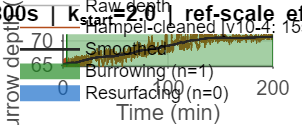

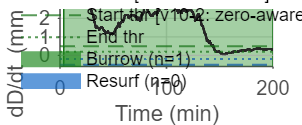

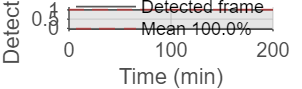

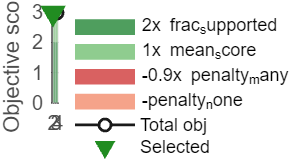


% ---------------------- PLOTS ----------------------------------------
C_BUR = [0.10 0.52 0.10]; C_RES = [0.05 0.40 0.78]; C_DEPTH = [0.15 0.15 0.15];
C_RATE = [0.15 0.15 0.15]; C_DET = [0.35 0.35 0.35]; C_CLEANED = [0.70 0.30 0.10];
ALPHA_SHADE = 0.22; LW_MAIN = 1.4; LW_THR = 1.0; FS_LABEL = 11; FS_TICK = 10;
FS_LEGEND = 9; FIG_W = 820; FIG_H = 340;
applyAxStyle = @(ax) set(ax,'FontSize',FS_TICK,'Box','off','TickDir','out','LineWidth',0.7,...
    'XColor',[0.3 0.3 0.3],'YColor',[0.3 0.3 0.3],'GridColor',[0.8 0.8 0.8],'GridAlpha',0.6);
figs = gobjects(0);

f1 = figure('Color','w','Position',[100 100 FIG_W FIG_H]); figs(end+1)=f1;
ax1 = axes('Parent',f1); hold(ax1,'on'); grid(ax1,'on');
hRaw = plot(ax1,t_min,D_in,'-','Color',[0.7 0.7 0.7],'LineWidth',0.8);
hCln = plot(ax1,t_min,D,'-','Color',C_CLEANED,'LineWidth',0.8);
hD   = plot(ax1,t_min,D_ref,'-','Color',C_DEPTH,'LineWidth',LW_MAIN);
d_valid = D_ref(isfinite(D_ref)); d_pad = max(0.5,(max(d_valid)-min(d_valid))*0.08);
ylim(ax1,[min(d_valid)-d_pad, max(d_valid)+d_pad]);
if bur_detected, shadeBoots(bur_final,C_BUR,ALPHA_SHADE); end
if res_detected, shadeBoots(res_final,C_RES,ALPHA_SHADE); end
uistack(hD,'top');
hBp=patch(NaN,NaN,C_BUR,'FaceAlpha',ALPHA_SHADE*3,'EdgeColor','none');
hRp=patch(NaN,NaN,C_RES,'FaceAlpha',ALPHA_SHADE*3,'EdgeColor','none');
legend(ax1,[hRaw,hCln,hD,hBp,hRp], ...
    {'Raw depth','Hampel-cleaned [v10-4: 15s]','Smoothed', ...
    sprintf('Burrowing (n=%d)',height(bur_final)), sprintf('Resurfacing (n=%d)',height(res_final))}, ...
    'Location','best','FontSize',FS_LEGEND,'Box','off');
xlabel(ax1,'Time (min)','FontSize',FS_LABEL); ylabel(ax1,'Burrow depth (mm)','FontSize',FS_LABEL);
title(ax1,sprintf('[Scale=%ds | k_{start}=%.1f | ref-scale effort=%.1f mm', ...
    ref_scale_s, bestConfig.kStartMult, effort_burrow_mm),'FontSize',FS_LABEL);
applyAxStyle(ax1);

f2 = figure('Color','w','Position',[100 100 FIG_W FIG_H]); figs(end+1)=f2;
ax2 = axes('Parent',f2); hold(ax2,'on'); grid(ax2,'on');
skip_frames = max(1,round(2*60/dt));
r_body = r_ref(min(skip_frames,numel(r_ref)):end); r_body = r_body(isfinite(r_body));
if numel(r_body)<10, r_body = r_ref(isfinite(r_ref)); end
r_lo = max(safePrctile(r_body,2),-5*start_thr_ref);
r_hi = min(safePrctile(r_body,98), 5*start_thr_ref);
r_lo = min(r_lo,-start_thr_ref*1.20); r_hi = max(r_hi,start_thr_ref*1.20);
if ~all(isfinite([r_lo r_hi]))||r_lo==r_hi, r_lo=-1; r_hi=1; end
hRt = plot(ax2,t_min,r_ref,'-','Color',C_RATE,'LineWidth',LW_MAIN); ylim(ax2,[r_lo,r_hi]);
if bur_detected, shadeBoots(bur_final,C_BUR,ALPHA_SHADE); end
if res_detected, shadeBoots(res_final,C_RES,ALPHA_SHADE); end
uistack(hRt,'top');
yline(ax2,0,'-','Color',[0.7 0.7 0.7],'LineWidth',0.6,'HandleVisibility','off');
hTs = yline(ax2,+start_thr_ref,'--','Color',C_BUR*0.85,'LineWidth',LW_THR,'Label','');
hTe = yline(ax2,+end_thr_ref,  ':','Color',C_BUR*0.85,'LineWidth',LW_THR,'Label','');
yline(ax2,-start_thr_ref,'--','Color',C_RES*0.85,'LineWidth',LW_THR,'HandleVisibility','off','Label','');
yline(ax2,-end_thr_ref,  ':','Color',C_RES*0.85,'LineWidth',LW_THR,'HandleVisibility','off','Label','');
hB2=patch(NaN,NaN,C_BUR,'FaceAlpha',ALPHA_SHADE*3,'EdgeColor','none');
hR2=patch(NaN,NaN,C_RES,'FaceAlpha',ALPHA_SHADE*3,'EdgeColor','none');
legend(ax2,[hRt,hTs,hTe,hB2,hR2], ...
    {'dD/dt [v10-1: ref=240s]','Start thr [v10-2: zero-aware]','End thr', ...
    sprintf('Burrow (n=%d)',height(bur_final)), sprintf('Resurf (n=%d)',height(res_final))}, ...
    'Location','best','FontSize',FS_LEGEND,'Box','off');
xlabel(ax2,'Time (min)','FontSize',FS_LABEL); ylabel(ax2,'dD/dt (mm hr^{-1})','FontSize',FS_LABEL);
applyAxStyle(ax2);

f3 = figure('Color','w','Position',[100 100 FIG_W 240]); figs(end+1)=f3;
ax3 = axes('Parent',f3); hold(ax3,'on'); grid(ax3,'on');
area(ax3,t_min,double(detected),'FaceColor',C_DET,'FaceAlpha',0.15,'EdgeColor','none','HandleVisibility','off');
hCov = plot(ax3,t_min,double(detected),'-','Color',C_DET,'LineWidth',0.9);
hMean = yline(ax3,det_frac,'--','Color',[0.75 0.2 0.2],'LineWidth',LW_THR,'Label','');
legend(ax3,[hCov,hMean],{'Detected frame',sprintf('Mean %.1f%%',100*det_frac)}, ...
    'Location','best','FontSize',FS_LEGEND,'Box','off');
xlabel(ax3,'Time (min)','FontSize',FS_LABEL); ylabel(ax3,'Detection','FontSize',FS_LABEL);
ylim(ax3,[-0.05 1.15]); yticks(ax3,[0 0.5 1]); yticklabels(ax3,{'0','0.5','1'}); applyAxStyle(ax3);

f4 = figure('Color','w','Position',[100 100 620 340]); figs(end+1)=f4;
ax4 = axes('Parent',f4); hold(ax4,'on'); grid(ax4,'on');
kVals = gridRows.kStartMult(:);
posMatrix=[gridRows.obj_term_frac_supported(:),gridRows.obj_term_mean_score(:)];
negMatrix=[-gridRows.obj_term_penalty_many(:),-gridRows.obj_term_penalty_none(:)];
hPos=bar(ax4,kVals,posMatrix,0.55,'stacked','EdgeColor','none');
hNeg=bar(ax4,kVals,negMatrix,0.55,'stacked','EdgeColor','none');
hPos(1).FaceColor=[0.31 0.62 0.37]; hPos(1).DisplayName='2x frac_supported';
hPos(2).FaceColor=[0.56 0.80 0.56]; hPos(2).DisplayName='1x mean_score';
hNeg(1).FaceColor=[0.85 0.38 0.38]; hNeg(1).DisplayName='-0.9x penalty_many';
hNeg(2).FaceColor=[0.96 0.64 0.54]; hNeg(2).DisplayName='-penalty_none';
hObj=plot(ax4,kVals,gridRows.obj,'o-','Color',[0.1 0.1 0.1],'MarkerFaceColor','w','LineWidth',1.4,'MarkerSize',6,'DisplayName','Total obj');
[~,bestIdx]=max(gridRows.obj);
hSel=plot(ax4,kVals(bestIdx),gridRows.obj(bestIdx),'v','MarkerSize',11,'MarkerFaceColor',[0.13 0.55 0.13],'MarkerEdgeColor','none','DisplayName','Selected');
yline(ax4,0,'-','Color',[0.65 0.65 0.65],'LineWidth',0.8,'HandleVisibility','off');
xlabel(ax4,'k_{start}','FontSize',FS_LABEL); ylabel(ax4,'Objective score','FontSize',FS_LABEL);
legend(ax4,[hPos,hNeg,hObj,hSel],'Location','eastoutside','FontSize',FS_LEGEND,'Box','off');
applyAxStyle(ax4);

for i=1:numel(figs)
    fn_png=fullfile(out_dir,sprintf('Fig_v10_%02d.png',i));
    fn_fig=fullfile(out_dir,sprintf('Fig_v10_%02d.fig',i));
    try, exportgraphics(figs(i),fn_png,'Resolution',300); catch, saveas(figs(i),fn_png); end
    savefig(figs(i),fn_fig);
end

fprintf('Saved Fig_v10_*.png/.fig\n');

Saved Fig_v10_*.png/.fig




% ===================================================================
%   LOCAL FUNCTIONS — CHANGED IN v10
% ===================================================================

% ----- [v10-4] HAMPEL FILTER: shorter window (15s default) --------
function D_out = hampelFilter(D_in, dt, win_s, k)
D_out = D_in(:); n = numel(D_out);
half_win = max(3, round(win_s / dt));   % [v10-4] typically 7 frames at 0.5 Hz
for i = 1:n
    lo = max(1,i-half_win); hi = min(n,i+half_win);
    win = D_out(lo:hi); wf = win(isfinite(win));
    if numel(wf) < 3, continue; end
    med = median(wf); sigma = 1.4826 * median(abs(wf-med));
    if isfinite(D_out(i)) && (abs(D_out(i)-med) > k*sigma) && sigma > 1e-9
        D_out(i) = med;
    end
end
end

% ----- [v10-2] ZERO-AWARE SIGMA ESTIMATOR -------------------------
function sigma = estimateSigmaRClipped(r_s)
% Robust sigma_r estimation that handles zero-inflated rate distributions.
%
% The v9 code used the bottom 30th percentile of ALL |rate| values.
% For auto-tracker input, frozen tracking plateaus cause ~16% of rates
% to be exactly zero even after movmedian smoothing.  The 30th percentile
% then falls to zero, sigma collapses to the floor (0.05 mm/hr), and all
% start/end thresholds are set at their absolute minimums.
%
% FIX [v10-2]: if more than 20% of rates are near-zero, adjust the
% percentile cut upward to skip the zero-inflated portion, so the MAD
% is estimated from the genuinely active rate distribution.
r = r_s(isfinite(r_s));
if isempty(r), sigma = 0.05; return; end
abs_r = abs(r);

zero_frac = mean(abs_r < 0.01);

if zero_frac > 0.20
    % Shift the percentile cut to effectively use the bottom 30% of
    % the non-zero part of the distribution.
    % e.g. zero_frac=0.50 -> effective_pct = 30/(1-0.50) = 60th pct overall
    %      = 30th pct of non-zero rates.
    effective_pct = min(90, 30.0 / max(0.01, 1.0 - zero_frac));
    cut    = prctile(abs_r, effective_pct);
    stable = r(abs_r <= cut & abs_r > 0.001);
else
    cut    = prctile(abs_r, 30);
    stable = r(abs_r <= cut);
end

if numel(stable) < 5
    stable = r(abs_r > 0.001);   % fall back to all non-zero
end
if numel(stable) < 5
    stable = r;                   % last resort: all finite rates
end

sigma = 1.4826 * mad(stable, 1);
if ~isfinite(sigma) || sigma < 1e-6
    sigma = 1.4826 * mad(r, 1);
end
if ~isfinite(sigma) || sigma < 1e-6, sigma = 0.05; end
end

% ----- [v10-5] HYSTERESIS WITH CORRECTED PLATEAU THRESHOLD --------
function [starts, ends] = detectBoutsHysteresisPlateau(r_s, D_s, startThr, endThr, ...
    k_start, k_end, direction, D_baseline, plateau_thr_mm)
% [v10-5] plateau_thr_mm replaces the hard-coded 0.5 mm in v9.
%         Default = min_amp_mm_floor = 1.0 mm.
%         This prevents the continuation rule from firing on noise-level
%         depth fluctuations for the auto-tracker signal.
if nargin < 9 || ~isfinite(plateau_thr_mm), plateau_thr_mm = 1.0; end

rdir = direction * r_s;
okStart = (rdir >= startThr); okStart(~isfinite(rdir)) = false;
okEnd   = (rdir <= endThr);   okEnd(~isfinite(rdir)) = false;

start_hold = conv(double(okStart), ones(k_start,1), 'same') >= k_start;
end_hold   = conv(double(okEnd),   ones(k_end,1),   'same') >= k_end;

starts = []; ends = []; state = 0; s0 = NaN;
for i = 1:numel(r_s)
    if state == 0
        if start_hold(i), state = 1; s0 = i; end
    else
        if end_hold(i)
            % [v10-5] only continue if depth has genuinely progressed past
            % the baseline by at least plateau_thr_mm (was 0.5 in v9)
            depth_progressed = isfinite(D_s(i)) && isfinite(D_baseline) && ...
                (direction * (D_s(i) - D_baseline) > plateau_thr_mm);
            if ~depth_progressed
                starts(end+1,1) = s0; ends(end+1,1) = i; %#ok<AGROW>
                state = 0; s0 = NaN;
            end
        end
    end
end
if state == 1
    starts(end+1,1) = s0; ends(end+1,1) = numel(r_s); %#ok<AGROW>
end
end

% ===================================================================
%   LOCAL FUNCTIONS — UNCHANGED FROM v9
% ===================================================================

function sigma = estimateSigmaDClipped(D_s)
dD = diff(D_s); dD = dD(isfinite(dD));
if isempty(dD), sigma = 0.01; return; end
cut = prctile(abs(dD),50); stable = dD(abs(dD)<=cut);
if numel(stable)<5, stable=dD; end
sigma = 1.4826*mad(stable,1);
if ~isfinite(sigma)||sigma<1e-9, sigma=0.01; end
end

function [D_s, r_s] = buildSmoothDepthRate(D_work, dt, smooth_depth_s, smooth_rate_s)
if ~isfinite(dt)||dt<=0, dt=1; end
if ~isfinite(smooth_depth_s)||smooth_depth_s<=0, smooth_depth_s=dt*3; end
if ~isfinite(smooth_rate_s) ||smooth_rate_s <=0, smooth_rate_s =dt*3; end
N = numel(D_work);
wD = max(3,round(smooth_depth_s/dt)); if ~isfinite(wD)||wD<1, wD=3; end
wD = min(wD,N); if mod(wD,2)==0, wD=wD+1; end
wR = max(3,round(smooth_rate_s/dt)); if ~isfinite(wR)||wR<1, wR=3; end
wR = min(wR,N); if mod(wR,2)==0, wR=wR+1; end
D_s    = movmean(D_work,wD,'omitnan','Endpoints','shrink');
r_mmph = gradient(D_s,dt)*3600;
r_s    = movmedian(r_mmph,wR,'omitnan');
end

function raw = initRawBoutTable()
raw = table(cell(0,1),zeros(0,1),zeros(0,1), ...
    zeros(0,1),zeros(0,1),zeros(0,1),zeros(0,1),zeros(0,1), ...
    zeros(0,1),zeros(0,1),zeros(0,1), ...
    zeros(0,1),zeros(0,1),zeros(0,1), ...
    zeros(0,1),zeros(0,1),zeros(0,1),zeros(0,1), ...
    zeros(0,1),zeros(0,1),zeros(0,1), ...
    'VariableNames',{'bout_type','scale_s','kStartMult', ...
    'start_idx','end_idx','start_time_s','end_time_s','duration_s', ...
    'start_depth_mm','end_depth_mm','delta_depth_mm', ...
    'mean_rate_mmph','p95_rate_mmph','max_rate_mmph', ...
    'frac_in_direction','coverage','nAnch','maxGapMin', ...
    'effort_mm','active_frac','conf_score'});
end

function x = fillmissingSafe(x)
try, x = fillmissing(x,'linear','EndValues','nearest');
catch
    idx = find(isfinite(x)); if isempty(idx), return; end
    x(1:idx(1)-1) = x(idx(1)); x(idx(end)+1:end) = x(idx(end));
    x = interp1(idx,x(idx),(1:numel(x))','linear','extrap');
end
end

function y = clamp01(x), y = max(0,min(1,x)); end
function m = nanmeanSafe(x), x=x(isfinite(x)); if isempty(x), m=NaN; else, m=mean(x); end, end
function q = safePrctile(x,p), x=x(isfinite(x)); if isempty(x), q=NaN; else, q=prctile(x,p); end, end

function [starts, ends] = detectBoutsHysteresis(r_s, startThr, endThr, k_start, k_end, direction)
rdir=direction*r_s; okStart=(rdir>=startThr); okStart(~isfinite(rdir))=false;
okEnd=(rdir<=endThr); okEnd(~isfinite(rdir))=false;
start_hold=conv(double(okStart),ones(k_start,1),'same')>=k_start;
end_hold  =conv(double(okEnd),  ones(k_end,1),  'same')>=k_end;
starts=[]; ends=[]; state=0; s0=NaN;
for i=1:numel(r_s)
    if state==0, if start_hold(i), state=1; s0=i; end
    else, if end_hold(i), starts(end+1,1)=s0; ends(end+1,1)=i; state=0; s0=NaN; end; end
end
if state==1, starts(end+1,1)=s0; ends(end+1,1)=numel(r_s); end
end

function [Mstarts,Mends] = mergeEventsByGap(starts, ends, t_s, merge_gap_s)
if isempty(starts), Mstarts=[]; Mends=[]; return; end
ms=starts(1); me=ends(1); Mstarts=[]; Mends=[];
for k=2:numel(starts)
    if t_s(starts(k))-t_s(me) <= merge_gap_s, me=max(me,ends(k));
    else, Mstarts(end+1,1)=ms; Mends(end+1,1)=me; ms=starts(k); me=ends(k); end
end
Mstarts(end+1,1)=ms; Mends(end+1,1)=me;
end

% [v10-3] Note: r_vel argument now receives r_s/3600 or r_s; effort is
% computed as sum(max(direction*r_vel,0))*dt to use the smooth rate.
function raw = buildRawBoutList(starts, ends, boutType, direction, ...
    t_s, dt, D_s, r_s, r_vel, detected, min_dur_s, min_amp_mm, sigma_dD, start_thr_mmph, L, scale_s, kStartMult)
raw = initRawBoutTable();
if isempty(starts), return; end
for k=1:numel(starts)
    s=starts(k); e=ends(k); if e<=s, continue; end
    dur_s=t_s(e)-t_s(s); if dur_s<min_dur_s, continue; end
    D0=D_s(s); D1=D_s(e); if ~isfinite(D0)||~isfinite(D1), continue; end
    delta_signed=D1-D0; delta_dir=direction*delta_signed;
    if delta_dir<min_amp_mm, continue; end
    dseg=diff(D_s(s:e)); epsD=max(0.01,0.5*sigma_dD);
    frac_dir=mean(direction*dseg>=-epsD,'omitnan');
    det_seg=detected(s:e); cov=mean(det_seg); nAnch=sum(det_seg);
    maxGapMin=maxConsecutiveGapMinutes(det_seg,dt);
    rdir=direction*r_s(s:e); rdir=rdir(isfinite(rdir));
    p95_rate=safePrctile(rdir,95); max_rate=max(rdir,[],'omitnan');
    mean_rate=delta_dir/max(1e-9,dur_s/3600);
    % [v10-3] use smooth rate velocity for effort
    effort_mm = sum(max(direction*r_vel(s:e),0),'omitnan') * dt / 3600;
    active_frac=mean(rdir>=start_thr_mmph,'omitnan');
    score_amp=clamp01(delta_dir/max(min_amp_mm,1e-6)); score_mon=clamp01((frac_dir-0.5)/0.4);
    score_cov=clamp01(cov/0.6); score_gap=clamp01(1-(maxGapMin/10));
    score_rate=clamp01(p95_rate/max(start_thr_mmph,1e-6));
    conf_score=0.30*score_amp+0.20*score_mon+0.20*score_cov+0.15*score_gap+0.15*score_rate;
    row=table({char(boutType)},scale_s,kStartMult,s,e,t_s(s),t_s(e),dur_s,...
        D0,D1,delta_signed,mean_rate,p95_rate,max_rate,frac_dir,cov,nAnch,maxGapMin,effort_mm,active_frac,conf_score,...
        'VariableNames',raw.Properties.VariableNames);
    raw=[raw;row]; %#ok<AGROW>
end
end

function maxGapMin = maxConsecutiveGapMinutes(det_seg, dt)
det_seg=det_seg(:); maxRun=0; cur=0;
for i=1:numel(det_seg)
    if ~det_seg(i), cur=cur+1; maxRun=max(maxRun,cur); else, cur=0; end
end
maxGapMin=(maxRun*dt)/60;
end

function clusters = clusterBoutsAcrossScales(raw, overlap_min_frac)
clusters=struct([]); if isempty(raw)||height(raw)==0, return; end
raw=sortrows(raw,'start_time_s'); used=false(height(raw),1); c=0;
for i=1:height(raw)
    if used(i), continue; end
    c=c+1; idxs=i; used(i)=true; cs=raw.start_time_s(i); ce=raw.end_time_s(i); changed=true;
    while changed
        changed=false;
        for j=1:height(raw)
            if used(j), continue; end
            if overlapsEnough(cs,ce,raw.start_time_s(j),raw.end_time_s(j),overlap_min_frac)
                used(j)=true; idxs(end+1)=j; cs=min(cs,raw.start_time_s(j)); ce=max(ce,raw.end_time_s(j)); changed=true;
            end
        end
    end
    st=raw.start_time_s(idxs); en=raw.end_time_s(idxs); sc=raw.scale_s(idxs); scores=raw.conf_score(idxs);
    clusters(c).start_time_s=median(st,'omitnan'); clusters(c).end_time_s=median(en,'omitnan');
    clusters(c).support_n=numel(unique(sc)); clusters(c).scales_list=unique(sc)'; clusters(c).score=nanmeanSafe(scores);
end
end

function tf = overlapsEnough(a1,a2,b1,b2,f)
da=max(1e-9,a2-a1); db=max(1e-9,b2-b1); inter=max(0,min(a2,b2)-max(a1,b1));
tf=(inter/min(da,db))>=f;
end

function ref_scale_s = chooseReferenceScale(scaleStats, scales_s)
if isempty(scaleStats), ref_scale_s=scales_s(1); return; end
scales=[scaleStats.scale_s]'; ms=[scaleStats.meanScore]'; weights=stateWeight(scaleStats);
ms(~isfinite(ms))=-Inf; [~,best]=max(ms.*weights); ref_scale_s=scales(best);
end

function w = stateWeight(scaleStats)
w=ones(numel(scaleStats),1);
for i=1:numel(scaleStats)
    if isfield(scaleStats(i),'weight')&&isfinite(scaleStats(i).weight), w(i)=scaleStats(i).weight; end
end
end

function idx = nearestIndex(t_s, tq)
[~,idx]=min(abs(t_s-tq)); idx=max(1,min(numel(t_s),idx));
end

% [v10-3] r_vel argument replaces v_work_mmps with r_s (smooth rate, mm/hr)
function finalTbl = buildFinalEnsembleTable(clusters, boutType, direction, ...
    t_s, dt, D_ref, r_ref, r_vel, detected, start_thr_mmph, min_amp_mm, sigma_dD, L, ...
    support_bonus_per_extra_scale, support_bonus_cap, ...
    frac_dir_min_high, frac_dir_min_med, min_cov_high, min_cov_med, min_anchors_high, min_anchors_med, ...
    max_gap_high, max_gap_med, support_min_scales)
finalTbl = table(zeros(0,1),cell(0,1),zeros(0,1),zeros(0,1),zeros(0,1),...
    zeros(0,1),zeros(0,1),zeros(0,1),zeros(0,1),zeros(0,1),zeros(0,1),...
    zeros(0,1),zeros(0,1),zeros(0,1),zeros(0,1),zeros(0,1),zeros(0,1),zeros(0,1),...
    zeros(0,1),zeros(0,1),zeros(0,1),cell(0,1),zeros(0,1),cell(0,1),...
    'VariableNames',{'bout_id','bout_type','start_time_min','end_time_min','duration_min',...
    'start_depth_mm','end_depth_mm','delta_depth_mm','start_depth_pct','end_depth_pct','delta_depth_pct',...
    'mean_rate_mmph','p95_rate_mmph','max_rate_mmph',...
    'frac_in_direction','coverage_detected','n_anchors','max_gap_inside_bout_min',...
    'bout_effort_mm','bout_active_frac','support_n_scales','scales_s_list','confidence_score','confidence_level'});
if isempty(clusters), return; end
nC=numel(clusters);
bout_id=zeros(nC,1); bout_type_col=cell(nC,1);
start_time_min=zeros(nC,1); end_time_min=zeros(nC,1); duration_min=zeros(nC,1);
start_depth_mm=zeros(nC,1); end_depth_mm=zeros(nC,1); delta_depth_mm=zeros(nC,1);
start_depth_pct=zeros(nC,1); end_depth_pct=zeros(nC,1); delta_depth_pct=zeros(nC,1);
mean_rate_mmph=zeros(nC,1); p95_rate_mmph=zeros(nC,1); max_rate_mmph=zeros(nC,1);
frac_in_direction=zeros(nC,1); coverage_detected=zeros(nC,1); n_anchors=zeros(nC,1);
max_gap_inside_bout_min=zeros(nC,1); bout_effort_mm=zeros(nC,1); bout_active_frac=zeros(nC,1);
support_n_scales=zeros(nC,1); scales_s_list=cell(nC,1);
confidence_score=zeros(nC,1); confidence_level=cell(nC,1);
for i=1:nC
    c=clusters(i); s=nearestIndex(t_s,c.start_time_s); e=nearestIndex(t_s,c.end_time_s);
    if e<s, tmp=s; s=e; e=tmp; end
    idx=s:e; Dseg=D_ref(idx); rseg=r_ref(idx); detSeg=detected(idx);
    covDet=mean(detSeg); detIdx=find(detSeg>0); nAnch=numel(detIdx);
    if isempty(detIdx), maxGapMin=(numel(idx)*dt)/60;
    else, gaps=diff(detIdx)-1; maxGapMin=(max([0;gaps(:)])*dt)/60; end
    startD=Dseg(1); endD=Dseg(end); dD=endD-startD;
    meanRate=mean(abs(rseg),'omitnan'); p95Rate=safePrctile(abs(rseg(isfinite(rseg))),95);
    maxRate=max(abs(rseg),[],'omitnan');
    if direction>0, fracDir=mean(rseg>0,'omitnan');
    else,           fracDir=mean(rseg<0,'omitnan'); end
    % [v10-3] effort from smooth rate velocity
    effort_mm = sum(max(direction*r_vel(idx),0),'omitnan') * dt / 3600;
    activeFrac=mean(abs(rseg)>=start_thr_mmph,'omitnan');
    suppN=numel(c.scales_list); scalesList=sprintf('%g,',c.scales_list);
    if ~isempty(scalesList), scalesList(end)=[]; end
    baseScore=0;
    if suppN>=support_min_scales, baseScore=baseScore+min(support_bonus_cap,support_bonus_per_extra_scale*max(0,suppN-support_min_scales)); end
    isHigh=(fracDir>=frac_dir_min_high)&&(covDet>=min_cov_high)&&(nAnch>=min_anchors_high)&&(maxGapMin<=max_gap_high);
    isMed =(fracDir>=frac_dir_min_med) &&(covDet>=min_cov_med) &&(nAnch>=min_anchors_med) &&(maxGapMin<=max_gap_med);
    score=baseScore+fracDir+covDet+0.1*nAnch;
    if isHigh, conf='HIGH'; elseif isMed, conf='MED'; else, conf='LOW'; end
    bout_id(i)=i; bout_type_col{i}=char(boutType);
    start_time_min(i)=t_s(s)/60; end_time_min(i)=t_s(e)/60; duration_min(i)=t_s(e)/60-t_s(s)/60;
    start_depth_mm(i)=startD; end_depth_mm(i)=endD; delta_depth_mm(i)=dD;
    start_depth_pct(i)=100*startD/L; end_depth_pct(i)=100*endD/L; delta_depth_pct(i)=100*dD/L;
    mean_rate_mmph(i)=meanRate; p95_rate_mmph(i)=p95Rate; max_rate_mmph(i)=maxRate;
    frac_in_direction(i)=fracDir; coverage_detected(i)=covDet; n_anchors(i)=nAnch;
    max_gap_inside_bout_min(i)=maxGapMin; bout_effort_mm(i)=effort_mm; bout_active_frac(i)=activeFrac;
    support_n_scales(i)=suppN; scales_s_list{i}=scalesList;
    confidence_score(i)=score; confidence_level{i}=conf;
end
finalTbl=table(bout_id,bout_type_col,start_time_min,end_time_min,duration_min,...
    start_depth_mm,end_depth_mm,delta_depth_mm,start_depth_pct,end_depth_pct,delta_depth_pct,...
    mean_rate_mmph,p95_rate_mmph,max_rate_mmph,frac_in_direction,coverage_detected,n_anchors,...
    max_gap_inside_bout_min,bout_effort_mm,bout_active_frac,support_n_scales,scales_s_list,...
    confidence_score,confidence_level,...
    'VariableNames',{'bout_id','bout_type','start_time_min','end_time_min','duration_min',...
    'start_depth_mm','end_depth_mm','delta_depth_mm','start_depth_pct','end_depth_pct','delta_depth_pct',...
    'mean_rate_mmph','p95_rate_mmph','max_rate_mmph','frac_in_direction','coverage_detected',...
    'n_anchors','max_gap_inside_bout_min','bout_effort_mm','bout_active_frac',...
    'support_n_scales','scales_s_list','confidence_score','confidence_level'});
end

function [qaClass,accept] = classifyTrialQA(det_frac,qa_primary,qa_secondary,qa_exploratory)
if det_frac>=qa_primary, qaClass='PRIMARY';
elseif det_frac>=qa_secondary, qaClass='SECONDARY';
elseif det_frac>=qa_exploratory, qaClass='EXPLORATORY';
else, qaClass='REJECT'; end
accept=det_frac>=qa_exploratory;
end

function tbl = addProtocolEvidenceColumns(tbl, min_amp_mm, start_thr_mmph, ...
    bio_frac_dir_min_high, bio_frac_dir_min_med, bio_support_min_high, bio_support_min_med, ...
    bio_score_min_high, bio_score_min_med, bio_dur_scale_min, trial_qa_class, trial_accept_event_inference)
if isempty(tbl)
    tbl.qa_conditioned_confidence_score=zeros(0,1); tbl.qa_conditioned_confidence_level=cell(0,1);
    tbl.bio_evidence_score=zeros(0,1); tbl.bio_evidence_level=cell(0,1);
    tbl.is_committed_event=false(0,1); tbl.trial_qa_class=cell(0,1); tbl.trial_accept_event_inference=false(0,1);
    return;
end
n=height(tbl);
amp_abs=abs(tbl.delta_depth_mm);
score_amp=arrayfun(@(x) clamp01(x/max(min_amp_mm,1e-6)), amp_abs);
score_mon=arrayfun(@(x) clamp01((x-0.5)/0.4), tbl.frac_in_direction);
score_sup=arrayfun(@(x) clamp01((x-1)/3), tbl.support_n_scales);
score_dur=arrayfun(@(x) clamp01(x/max(bio_dur_scale_min,1e-6)), tbl.duration_min);
score_rate=arrayfun(@(x) clamp01(x/max(start_thr_mmph,1e-6)), tbl.p95_rate_mmph);
bio_score=0.35*score_amp+0.25*score_mon+0.20*score_sup+0.10*score_dur+0.10*score_rate;
bio_level=repmat({'LOW'},n,1);
for i=1:n
    if amp_abs(i)>=min_amp_mm
        if tbl.support_n_scales(i)>=bio_support_min_high&&tbl.frac_in_direction(i)>=bio_frac_dir_min_high&&bio_score(i)>=bio_score_min_high
            bio_level{i}='HIGH';
        elseif tbl.support_n_scales(i)>=bio_support_min_med&&tbl.frac_in_direction(i)>=bio_frac_dir_min_med&&bio_score(i)>=bio_score_min_med
            bio_level{i}='MED';
        end
    end
end
tbl.qa_conditioned_confidence_score=tbl.confidence_score; tbl.qa_conditioned_confidence_level=tbl.confidence_level;
tbl.bio_evidence_score=bio_score; tbl.bio_evidence_level=bio_level;
tbl.is_committed_event=trial_accept_event_inference&ismember(string(bio_level),["MED","HIGH"]);
tbl.trial_qa_class=repmat({trial_qa_class},n,1);
tbl.trial_accept_event_inference=repmat(trial_accept_event_inference,n,1);
end

function shadeBoots(tbl, color, alpha_base)
if isempty(tbl), return; end; yl=ylim;
for k=1:height(tbl)
    xs=tbl.start_time_min(k); xe=tbl.end_time_min(k);
    lvl=upper(string(tbl.confidence_level{k}));
    if lvl=="HIGH", a=min(0.45,alpha_base*1.8); ls='-';
    elseif lvl=="MED", a=min(0.32,alpha_base*1.35); ls='--';
    else, a=max(0.10,alpha_base*0.85); ls=':'; end
    patch([xs xe xe xs],[yl(1) yl(1) yl(2) yl(2)],color,'FaceAlpha',a,'EdgeColor','none','HandleVisibility','off');
    plot([xs xs],yl,ls,'Color',color*0.85,'LineWidth',0.8,'HandleVisibility','off');
    plot([xe xe],yl,ls,'Color',color*0.85,'LineWidth',0.8,'HandleVisibility','off');
end
end


function cfg = applyDetectorVariant(cfg)

cfg.use_multiscale              = true;
cfg.use_adaptive_thresholds     = true;
cfg.use_cross_scale_clustering  = true;
cfg.use_qa_logic                = true;
cfg.use_bio_evidence            = true;

switch lower(cfg.variant)
    case 'full'
    case 'simple_detector'
        cfg.use_multiscale             = false;
        cfg.use_adaptive_thresholds    = false;
        cfg.use_cross_scale_clustering = false;
        cfg.use_qa_logic               = false;
        cfg.use_bio_evidence           = false;
    case 'no_multiscale'
        cfg.use_multiscale             = false;
        cfg.use_cross_scale_clustering = false;
    case 'no_adaptive_thresholds'
        cfg.use_adaptive_thresholds    = false;
    case 'no_qa_logic'
        cfg.use_qa_logic               = false;
    case 'no_bio_evidence'
        cfg.use_bio_evidence           = false;
    otherwise
        error('Unknown detector variant: %s', cfg.variant);
end
end

function clusters = rawBoutRowsToClusters(rawTbl)
clusters = struct([]);
if isempty(rawTbl) || height(rawTbl)==0
    return;
end
clusters = repmat(struct('start_time_s',[],'end_time_s',[],'support_n',[],'scales_list',[],'score',[]), height(rawTbl), 1);
for i = 1:height(rawTbl)
    clusters(i).start_time_s = rawTbl.start_time_s(i);
    clusters(i).end_time_s   = rawTbl.end_time_s(i);
    clusters(i).support_n    = 1;
    clusters(i).scales_list  = rawTbl.scale_s(i);
    clusters(i).score        = rawTbl.conf_score(i);
end
end

function tbl = addProtocolEvidenceColumns_OFF(tbl, trial_qa_class, trial_accept_event_inference)
if isempty(tbl)
    tbl.qa_conditioned_confidence_score=zeros(0,1); tbl.qa_conditioned_confidence_level=cell(0,1);
    tbl.bio_evidence_score=zeros(0,1); tbl.bio_evidence_level=cell(0,1);
    tbl.is_committed_event=false(0,1); tbl.trial_qa_class=cell(0,1);
    tbl.trial_accept_event_inference=false(0,1);
    return;
end
n = height(tbl);
tbl.qa_conditioned_confidence_score = tbl.confidence_score;
tbl.qa_conditioned_confidence_level = tbl.confidence_level;
tbl.bio_evidence_score = nan(n,1);
tbl.bio_evidence_level = repmat({'OFF'}, n,1);
tbl.is_committed_event = false(n,1);
tbl.trial_qa_class = repmat({trial_qa_class}, n,1);
tbl.trial_accept_event_inference = repmat(trial_accept_event_inference, n,1);
end